# Parameters

#### Scene

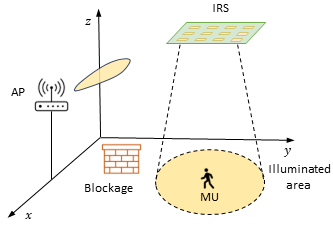

p_AP = [2 0 2]; % BS position
%The IRS is located in the yz plane and it illuminates a MU in parallel
%plane to the IRS
p_IRS = [0 2 3]; % IRS position
%The MU is located in a parallel plane to yz where the IRS is located, the
%user moves within this plane that is 3m distant from the IRS as indicated
%by the x-coordinate
p_focus = [3 2 3]; % center point; the MU and the IRS are both oriented along the perpendicular to the IRS surface, which is perpendicular to the yz plane

#### Simulation parameters

numPackets=100;%total of packets to transmit per position
N = 1e2; % number of points for grid discretization in the ground plane
Dobs = 10; % A D*D square observation area in the ground plane

%MU's mobility
radius_MU=5;%MU's maximum radius
total_pos_points=5;
r_MU=linspace(0,radius_MU,total_pos_points);
angle_MU=linspace(0,2*pi,total_pos_points);

#### Propagation parameters

f = 60e9; % frequency
c = physconst('lightspeed'); % speed of light
lambda = c/f; % wavelength


**802.11ad parameters**

Ptx_dBm = 30; % transmit power in dBm
Ptx = db2pow(Ptx_dBm-30);
% Create a configuration object
cfgDMG = wlanDMGConfig;
cfgDMG.MCS="1";
cfgDMG.PSDULength = 4096; % PSDULength in bytes
idleTime=20;% Idle time between packets in us
Ngi = 64; % Fixed GI length defined in the standard (20.6.3.2.5)


#### Channel Impairment

The maximum tolerance for the transmitter center frequency must be within [-20, +20] ppm [ [1](about:blank<#13%3E) ]. In this example, a clock accuracy of 20ppm is considered to derive the CFO. The transmitted signal is delayed by 500 samples and also appended by 100 zero samples at the end to account for delays from TGay channel filtering.

ppm = 20;                 % Clock accuracy to drive the CFO (ppm)
freqOffset = ppm*1e-6*f; % Carrier frequency offset (Hz)
delay = 500;              % Sample to delay the waveform
zeroPadding = 100;        % Add trailing zeros to allow for channel delay

#### Receiver parameters

NoiseFloor = -89.9;    % STA noise floor in dBm
var_noise=db2pow(NoiseFloor-30);


#### IRS parameters

Qy=160;
Qz=160;
dy = lambda/2; % element spacing
dz = lambda/2; % element spacing
Ly = Qy*dy; % IRS dimension
Lz =Qz*dz; % IRS dimension
Dp_y_tot = [1.5]; % Wide beam parameter
Dp_z_tot = Dp_y_tot; % Wide beam parameter

gtilde = 4*pi*dy*dz/(lambda^2); % unit-less unit-cell factor

%Operating regime:
D = sqrt(Ly^2+Lz^2);
dnear = sqrt(8*D^3/lambda);
dfar = 2*D^2/lambda;

**Plotting parameters**

fontsize=15;

#### References

[1] WLAN PPDU Structure, [https://www.mathworks.com/help/wlan/gs/wlan-ppdu-structure.html](https://www.mathworks.com/help/wlan/gs/wlan-ppdu-structure.html)